# Wave propagation through air and thin lens

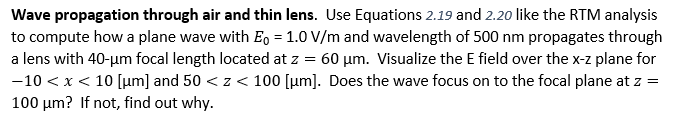

All lengths are in [m].

clear

E0 = 1.0;
lam = 500e-9;  % wavelength
f = 40e-6;  % focal length

k = 2*pi/lam

k = 1.2566e+07

## Compute E(x,y,z) slab by slab and visualize E(x,z).

z array to be investigated

dz = 0.1e-6;  % 0.1 um
z = 50e-6:dz:100e-6;  nz = length(z);

2D grid of (x,y)

x = -10e-6:dz:10e-6;  nx = length(x);  % dx = dy = dz
y = -10e-6:dz:10e-6;  ny = length(y);

[gx,gy] = ndgrid(x,y);
size(gx)

ans =    201   201


3D array of E(x,y,z) by computing E(x,y,z+dz) from E(x,y,z)

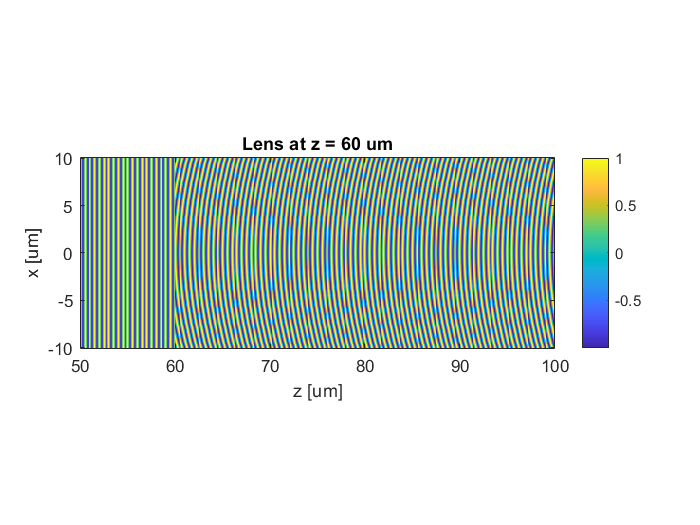

E = complex(zeros(nx,ny,nz));
E(:,:,1) = E0 * exp(1i*k*z(1));

for iz=2:nz
    E(:,:,iz) = E(:,:,iz-1) .* exp(1i * k * dz);  % multiply the transfer function of air
    if z(iz) == 60e-6  % lens position
        E(:,:,iz) = E(:,:,iz) .* exp(-1i * k/2/f .* (gx.^2+gy.^2));  % additionally multiply the transfer function of lens
    end
end

iy0 = find(y==0);  % the y index for y = 0

figure
imagesc(z*1e6,x*1e6,real(squeeze(E(:,iy0,:))))
set(gca,'ydir','normal')
axis image
colorbar
xlabel('z [um]')
ylabel('x [um]')
title('Lens at z = 60 um')

- Something is wrong!